# PRACTICA 4. FILTROS FIR

Para la misma señal x[n]=1,5 cos(0,2pin)+0,1 cos(0,35pin)+0,7 cos(0,6pin) 

Filtradla paso bajo (w/pi = 0,2), paso banda (w/pi = 0,35) y paso alto (w/pi = 0,6) para que sólo quede un tono, usando filtros Butterworth, Chebyshev tipos I y II y elíptico Representadlo en tiempo (comparando con la señal que debería dar) y frecuencia (filtro y señal)

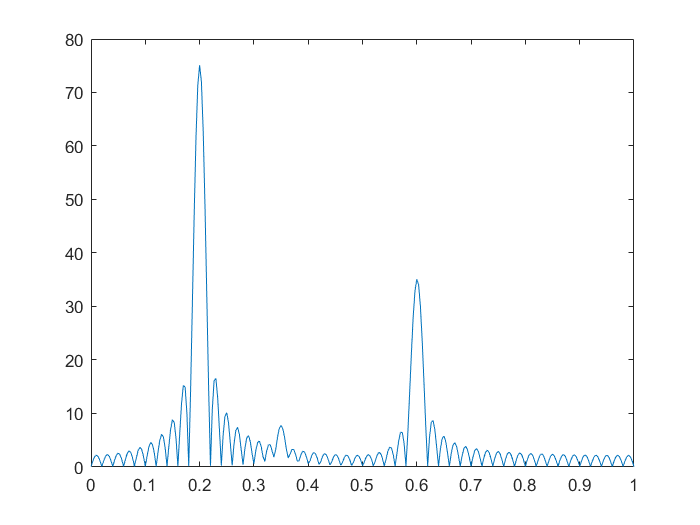

N=100;
n=linspace(0,N-1,N);
omega=linspace(0,pi,301); 
omeganormalizada=linspace(0,pi/pi,301);
x=1.5.*cos(0.2*pi.*n)+0.1.*cos(0.35*pi.*n)+0.7.*cos(0.6*pi.*n);
X=DTFT(x,n,omega);
plot(omeganormalizada,abs(X)) %para comprobar que mi señal está bien definida

**Paso bajo con Butterworth**

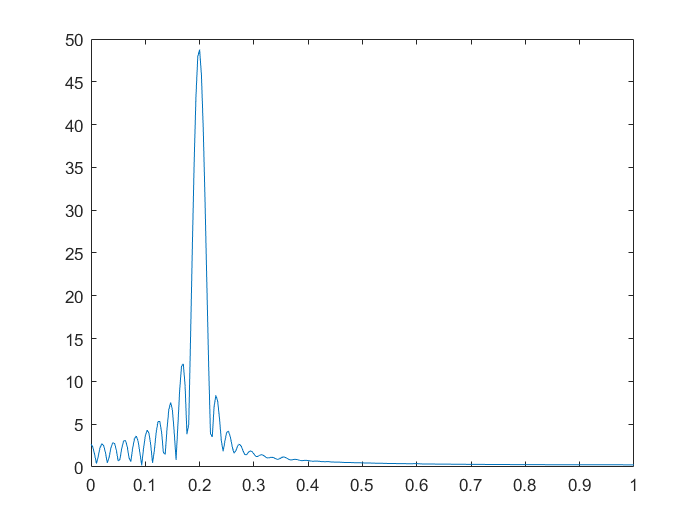

N1=5; %orden del filtro, el orden 2 no es costoso pero no acaba de filtrar bien
%PASO 1 [b,a]
[b,a]=butter(N1,0.2); %el orden del filtrom es como minimo 2 y habrá que ir probando valores hasta dar con una forma correcta
y=filter(b,a,x);
Y=DTFT(y,n,omega);
plot(omeganormalizada,abs(Y)) %Para comprobar que el orden del filtro es correcto, solo queda la frecuencia paso bajo

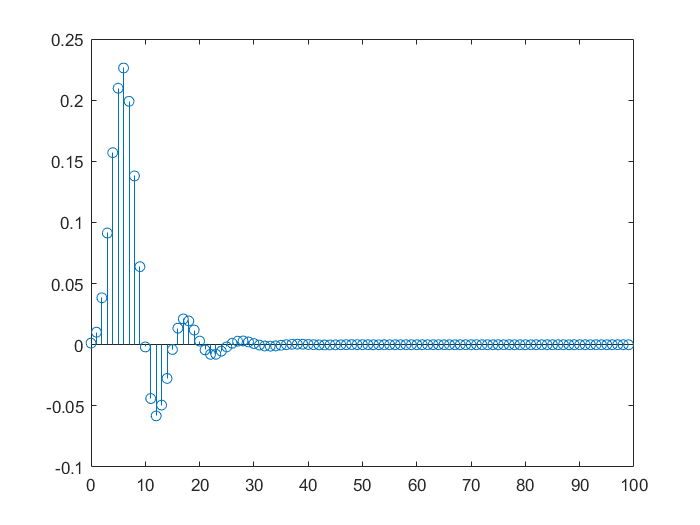

%PASO 2 h[n]
h=filter(b,a,delta(n,0));
stem(n,h)

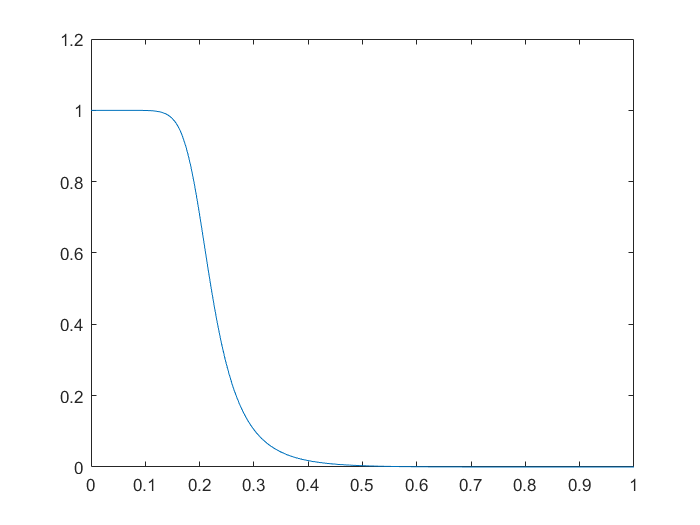

H=DTFT(h,n,omega);
plot(omeganormalizada,abs(H)) %Para seguir comprpobando que el orden del filtro es correcto, represento h en tiempo y frecuencia

%PASO 3, debo encontrar los Nh=! 0
maxh=max(h) %el max de h me da en 0.28

maxh = 0.2263

ind=find(abs(h)>max(abs(h)/20)) %busco aquellos valores que sean mayores que el maximo/20

ind =      3     4     5     6     7     8     9    10    12    13    14    15    17    18    19    20


Nh=max(ind) % me da que son 8 valores, de los cuales el mayor es el 10

Nh = 20

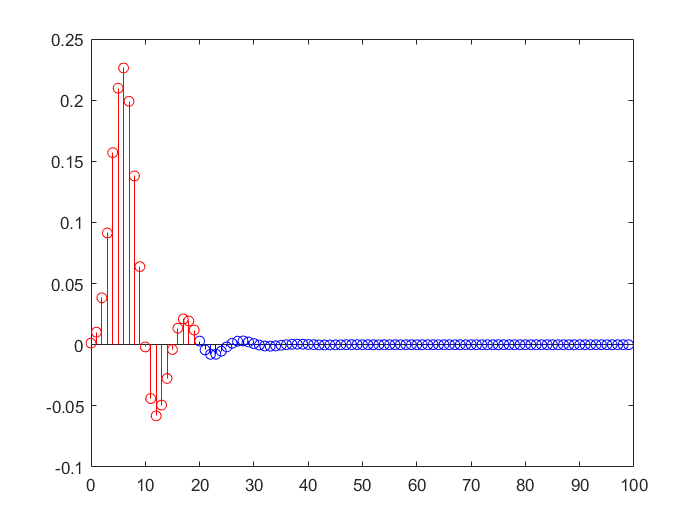

%PASO 4, debo descartar los Nh-1 primeros valores
y_definitiva=y(Nh:end);
n_definitiva=n(Nh:end);
stem(n,h,'b');hold on;stem(n(1:Nh),h(1:Nh), 'r'); hold off %hasta el final o principio??

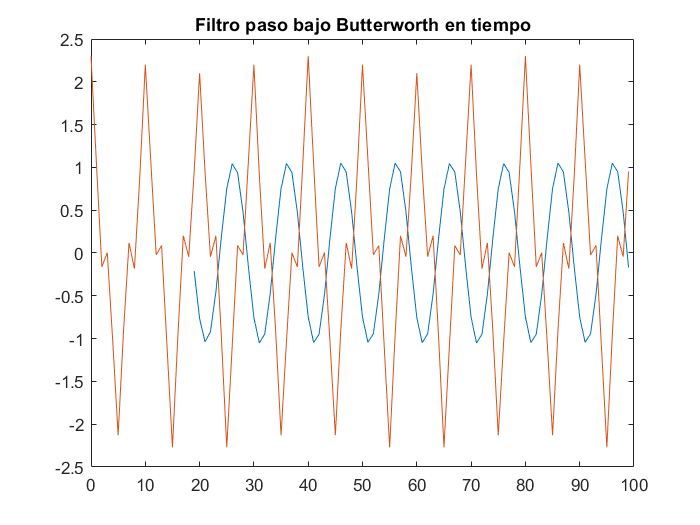

plot(n_definitiva,real(y_definitiva),n,real(x))
title('Filtro paso bajo Butterworth en tiempo')

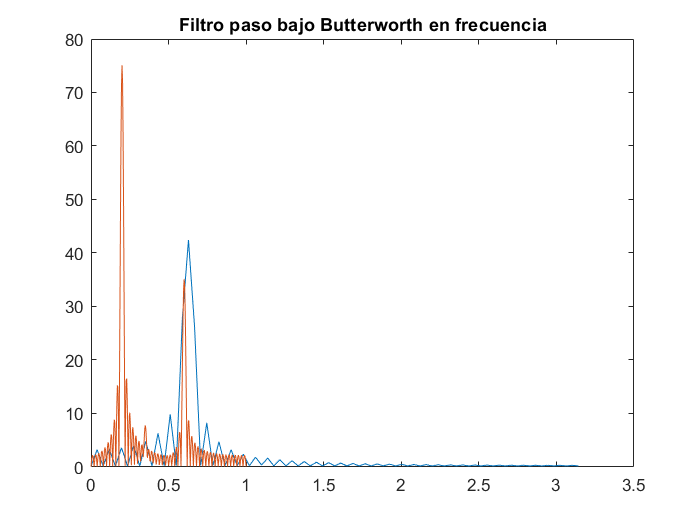

omega_definitiva=linspace(0,pi,length(y_definitiva));
Y_definitiva=DTFT(y_definitiva,n_definitiva,omega_definitiva);
plot(omega_definitiva,abs(Y_definitiva),omeganormalizada,abs(X)) 
title('Filtro paso bajo Butterworth en frecuencia')

**Paso bajo con Chebychev 1 (solo controla la parte de arriba, zona de paso)**

%PASO 1 
N_C1=2 %orden del filtro, tengo que fijarme al representar la salida y en frecuencia al estar multiplicada la segunda por

N_C1 = 2

% un valor pequeño 0.1, basta conj un valor de orden de filtro pequeño para poder eliminarla
Rp_C1=1

Rp_C1 = 1

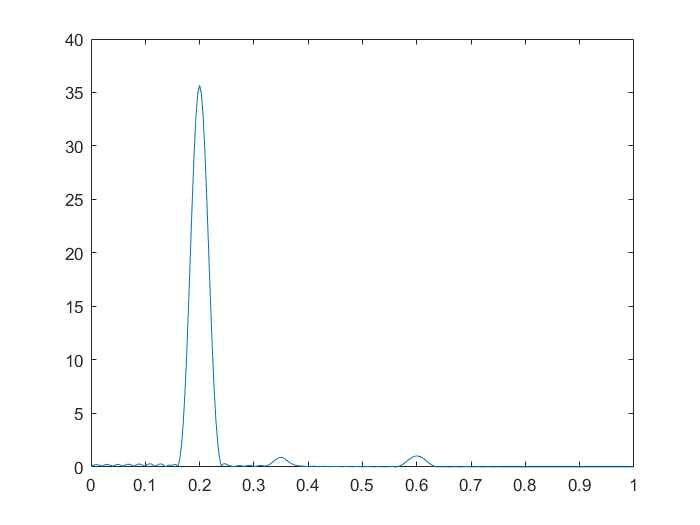

[d,c]=cheby1(N_C1,Rp_C1,0.2); %debo ver si aumento la N sin que se me dispare la longitud de elementos
y_C1=filter(d,c,x);
w_Hammimg=hamming(N); %utilizo una ventana mejor
yham_C1=y_C1.*w_Hammimg';
YHAM_C1=DTFT(yham_C1,n,omega);
plot(omeganormalizada,abs(YHAM_C1)) %Para comprobar que el orden del filtro es correcto, solo queda la frecuencia paso bajo

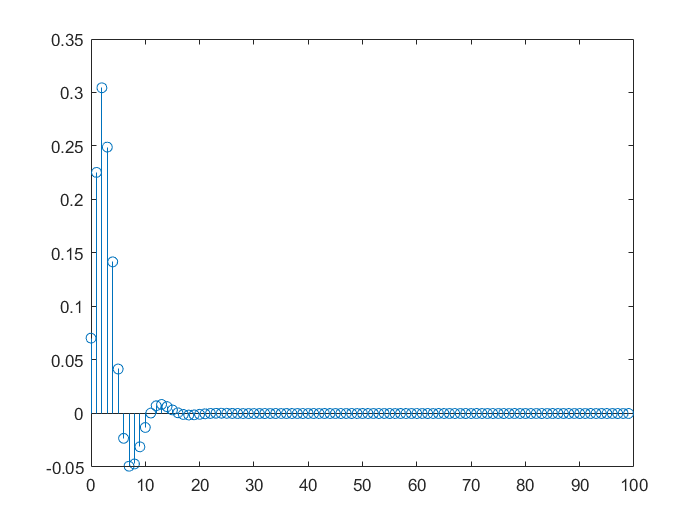

%PASO 2 h[n]
h_C1=filter(d,c,delta(n,0));
stem(n,h_C1)

H_C1=DTFT(h_C1,n,omega)

H_C1 =    0.8913 + 0.0000i   0.8912 - 0.0143i   0.8912 - 0.0286i   0.8911 - 0.0430i   0.8909 - 0.0574i   0.8907 - 0.0719i   0.8905 - 0.0865i   0.8902 - 0.1012i   0.8898 - 0.1160i   0.8893 - 0.1310i   0.8887 - 0.1462i   0.8881 - 0.1615i   0.8873 - 0.1771i   0.8864 - 0.1929i   0.8853 - 0.2089i   0.8840 - 0.2252i   0.8825 - 0.2417i   0.8808 - 0.2586i   0.8788 - 0.2757i   0.8766 - 0.2932i   0.8740 - 0.3110i   0.8711 - 0.3292i   0.8678 - 0.3477i   0.8640 - 0.3665i   0.8598 - 0.3857i   0.8551 - 0.4053i   0.8497 - 0.4252i   0.8438 - 0.4455i   0.8372 - 0.4661i   0.8298 - 0.4871i   0.8216 - 0.5083i   0.8126 - 0.5298i   0.8026 - 0.5516i   0.7917 - 0.5735i   0.7797 - 0.5956i   0.7667 - 0.6177i   0.7524 - 0.6399i   0.7370 - 0.6620i   0.7203 - 0.6839i   0.7022 - 0.7056i   0.6828 - 0.7269i   0.6621 - 0.7477i   0.6399 - 0.7680i   0.6164 - 0.7875i   0.5914 - 0.8061i   0.5652 - 0.8237i   0.5376 - 0.8401i   0.5088 - 0.8552i   0.4789 - 0.8689i   0.4479 - 0.8810i


plot(n,real(H_C1)) %Para seguir comprpobando que el orden del filtro es correcto, represento h en tiempo y frecuencia

Error using plot
Vectors must be the same length.

%PASO 3, debo encontrar los Nh=! 0
maxh_C1=max(h_C1) 
ind_C1=find(abs(h_C1)>max(abs(h_C1)/20)) %busco aquellos valores que sean mayores que el maximo/20
Nh_C1=max(ind_C1) % me da que son 8 valores, de los cuales el mayor es el 10
%PASO 4, debo descartar los Nh-1 primeros valores
y_definitiva_C1=y(Nh_C1:end)
n_definitiva_C1=n(Nh_C1:end)
plot(n_definitiva_C1,real(y_definitiva_C1),n,real(x))
title('Filtro paso bajo Chebychev tipo 1 en tiempo')
omega_definitiva_C1=linspace(0,pi,length(y_definitiva_C1));
Y_definitiva_C1=DTFT(y_definitiva_C1,n_definitiva_C1,omega_definitiva_C1);
plot(omega_definitiva_C1,abs(Y_definitiva_C1),omega,abs(X)) 
title('Filtro paso bajo Chebychev tipo 1 en frecuencia')


**Paso bajo con Chebychev 2**

**Paso bajo elíptico**

Filtro Paso banda

Con Nf 30 o 40 filtra bien. Con 20 pierde amplitud. Con números no múltiplos de 10 no filtra realmente la componente a 0,2

Nf = 24;
H  = ones(1,Nf)
k  = linspace(0,Nf-1,Nf);
kf  = k*2/Nf;
omp = 0.25;
oms = 0.3;
H1  = pasobajo(kf,omp,oms);
omp = 0.4;
oms = 0.45;
H2  = pasobajo(kf,omp,oms);
H  = exp(-1j*2*pi*k/2)-(H2-H1)
H  = H2-H1;
h  = ifft(H)
n1 = linspace(-Nf+1,N-1,N+Nf-1);
x1 = 1.5*cos(f1*pi*n1)+0.1*cos(f2*pi*n1)+0.7*cos(f3*pi*n1);
y1 = ifft(fft(x1).*fft(h,N+Nf-1));
y  = y1(Nf:N+Nf-1);
Yw = DTFT(y.*hamming(N)',n,w);
Hw = DTFT(h,k,w);
subplot(221);plot(n-Nf/2,real(y),'r',n,0.1*cos(f2*pi*n),'b');subplot(222);plot(w/pi,abs(Xw),w/pi,abs(Yw))
subplot(223);stem(k,real(h));subplot(224);plot(w/pi,abs(Hw),kf,abs(H),'o');axis([0 1 0 1.2])


f1 = 0.2;
f2 = 0.35;
f3 = 0.6;
N  = 100;
n  = linspace(0,N-1,N);
x  = 1.5*cos(f1*pi*n)+0.1*cos(f2*pi*n)+0.7*cos(f3*pi*n);
w  = linspace(0,pi,301);
Xw = DTFT(x,n,w);
plot(w/pi,abs(Xw))

Filtro paso banda Chebyshev tipo II

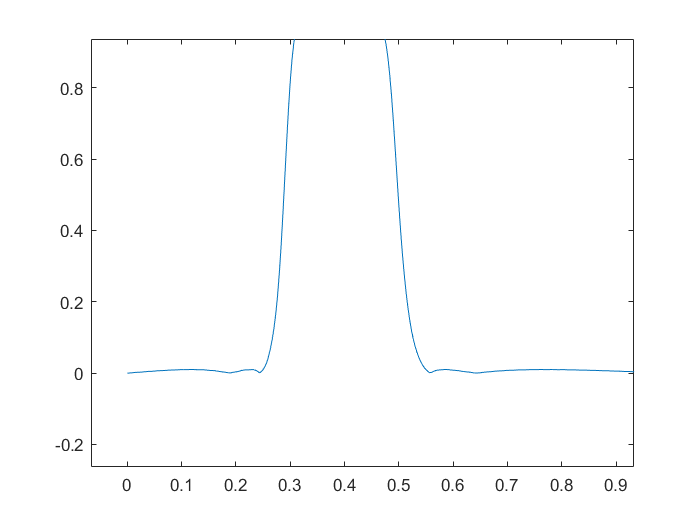

[b,a] = cheby2(5,40, [0.25 0.55]);
hc    = filter(b,a,delta(n,0));
Hc=DTFT(hc,n,w);
plot(w/pi,abs(Hc))

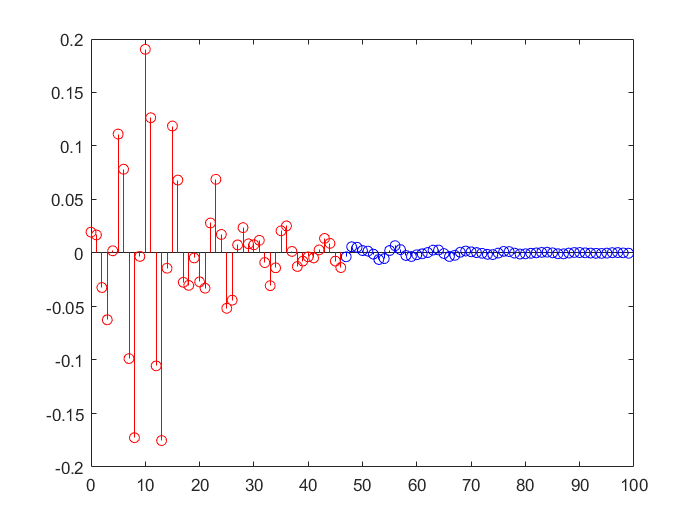

Nc    = max(find(abs(hc)>max(hc)/20)); 
stem(n,hc,'b');hold on; stem(n(1:Nc),hc(1:Nc),'r'); hold off

Aplicación de bloque a la señal de salida y ventana en la representación:

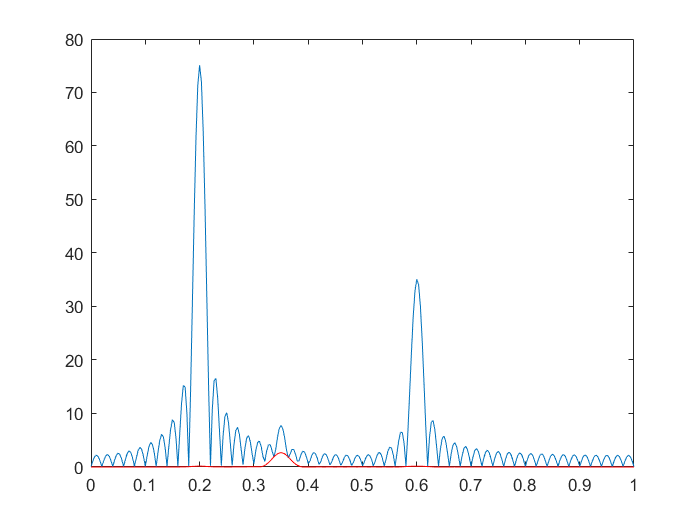

nc = linspace(-Nc+1,N-1,N+Nc-1);
xc  = 1.5*cos(f1*pi*nc)+0.1*cos(f2*pi*nc)+0.7*cos(f3*pi*nc);
yci = filter(b,a,xc);
yc  = yci(Nc:N+Nc-1);
Yw = DTFT(yc.*hamming(N)',n,w);
plot(w/pi,abs(Xw),w/pi,abs(Yw),'r')

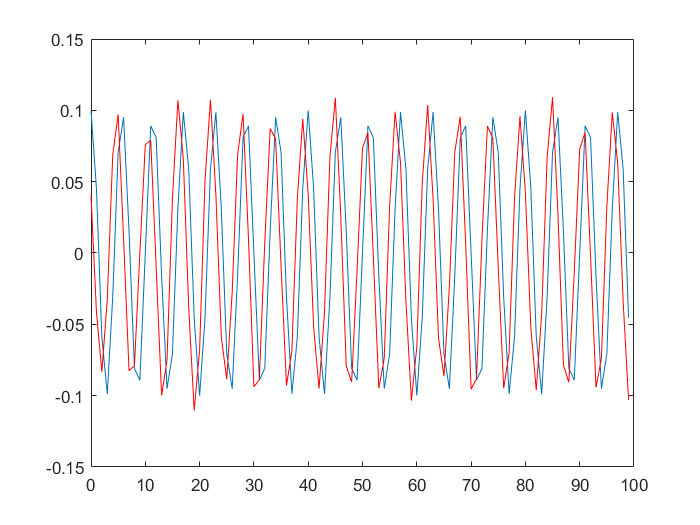

plot(n,0.1*cos(f2*pi*n),n,yc,'r')

Filtro paso alto Elíptico

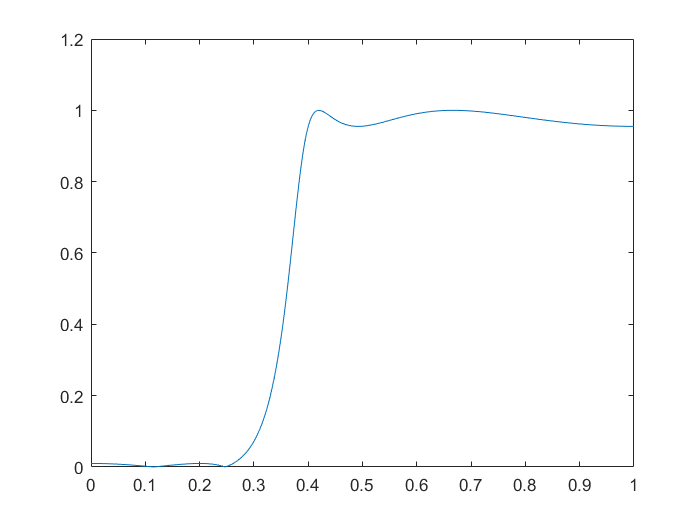

[b,a] = ellip(4,0.4,40,0.4,'high');
he    = filter(b,a,delta(n,0));
He=DTFT(he,n,w);
plot(w/pi,abs(He))

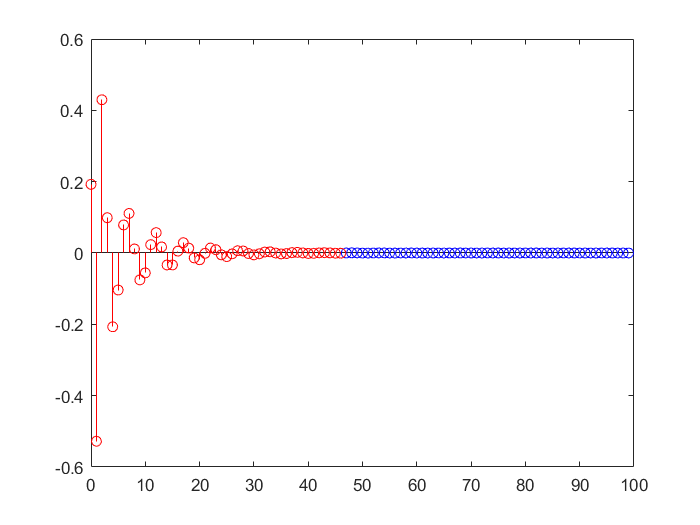

Ne    = max(find(abs(he)>max(he)/20)); 
stem(n,he,'b');hold on; stem(n(1:Nc),he(1:Nc),'r'); hold off

Aplicación de bloque a la señal de salida y ventana en la representación:

ne = linspace(-Ne+1,N-1,N+Ne-1);
xe  = 1.5*cos(f1*pi*ne)+0.1*cos(f2*pi*ne)+0.7*cos(f3*pi*ne);
yei = filter(b,a,xe);
ye  = yei(Ne:N+Ne-1);
Yw = DTFT(ye.*hamming(N)',n,w);

Cannot find an exact (case-sensitive) match for 'dtft'

The closest match is: DTFT in C:\Users\olaia\OneDrive\Documentos\SENSORES\DTFT.m

plot(w/pi,abs(Xw),w/pi,abs(Yw),'r')
plot(n,0.7*cos(f3*pi*n),n,ye,'r')
